## **Introduction to Bio-Informatics**

# **Assignment 1: Sequence Statistics and Gene Finding**

**Chiara Paglioni (i6249782)**

Like humans, Neanderthals had not only nuclear DNA, but also mitochondrial DNA in all their cells.  Like humans, the mitochondria of neanderthals contained 13 coding genes and 24 non-coding genes. The neanderthal mitochondrial genome has accession number 'NC_011137'.

**Neanderthal mitochondrial genome:**

data = getgenbank('NC_011137', 'SequenceOnly', true);
data

data = 'GATCACAGGTCTATCACCCTATTAACCACTCACGGGAGCTCTCCATGCATTTGGTATTTTCGTCTGGGGGGTGTGCACGCGATAGCATTGCGAGACGCTGGAGCCGGAGCACCCTATGTCGCAGTATCTGTCTTTGATTCCTGCCCCATTCCATTATTTATCGCACCTACGTTCAATATTACAGGCGAGCATACTTACTGAAGTGTGTTAATTAATTAATGCTTGTAGGACATAATAATAACGACTAAATGTCTGCACAGCTGCTTTCCACACAGACATCATAACAAAAAATTTCCACCAAACCCCCCCTCCCCCGCTTCTGGCCACAGCACTTAAACACATCTCTGCCAAACCCCAAAAACAAAGAACCCTAACACCAGCCTAACCAGATTTCAAATTTTATCTTTTGGCGGTATACACTTTTAACAGTCACCCCCTAACTAACACATTATTTTCCCCTCCCACTCCCATACTACTAATCTCATCAATACAACCCCCGCCCATCCTACCCAGCACACACCGCTGCTAACCCCATACCCCGAGCCAACCAAACCCCAAAGACACCCCCCACAGTTTATGTAGCTTACCTCCTCAAAGCAATACACTGAAAATGTTTAGACGGGCTCACATCACCCCATAAACAAATAGGTTTGGTCCTAGCCTTTCTATTAGCTCTTAGTAAGATTACACATGCAAGCATCCCCATTCCAGTGAGTTCACCCTCTAAATCACCACGATCAAAAGGGACAAGCATCAAGCACGCAACAATGCAGCTCAAAACGCTTAGCCTAGCCACACCCCCACGGGAAACAGCAGTGATAAGCCTTTAGCAATAAACGAAAGTTTAACTAAGCTATACTAACCCCAGGGTTGGTCAATTTCGTGCCAGCCACCGCGGTCACACGATTAACCCAAGTCAATAGAAGCCGGCGTAAAGAGTGTTTTAGATCACCCCCTCCCCAATAAAGCTAAAACTCACCTGAGTTGTAAAA

**1. How does the number of genes stated above compare with the number of ORFs you find?**	

**ORFs:**

The ORFs of the mitochondria of neanderthals are retrieved throughout the function **seqshoworfs**. 

It is possible to divide the ORFs in two categories: 

- ORFs that contain real genes 

- ORFs that occur by chance

The second kind of ORFs can be discarded since they are part of the "junk" of the DNA. In order to classify the ORFs, a minum length *k* is calculated. Every ORF of length greater or equal to *k* contains real genes while the remaining candidate genes belong to the second category of ORFs thus, they can be rejected. 

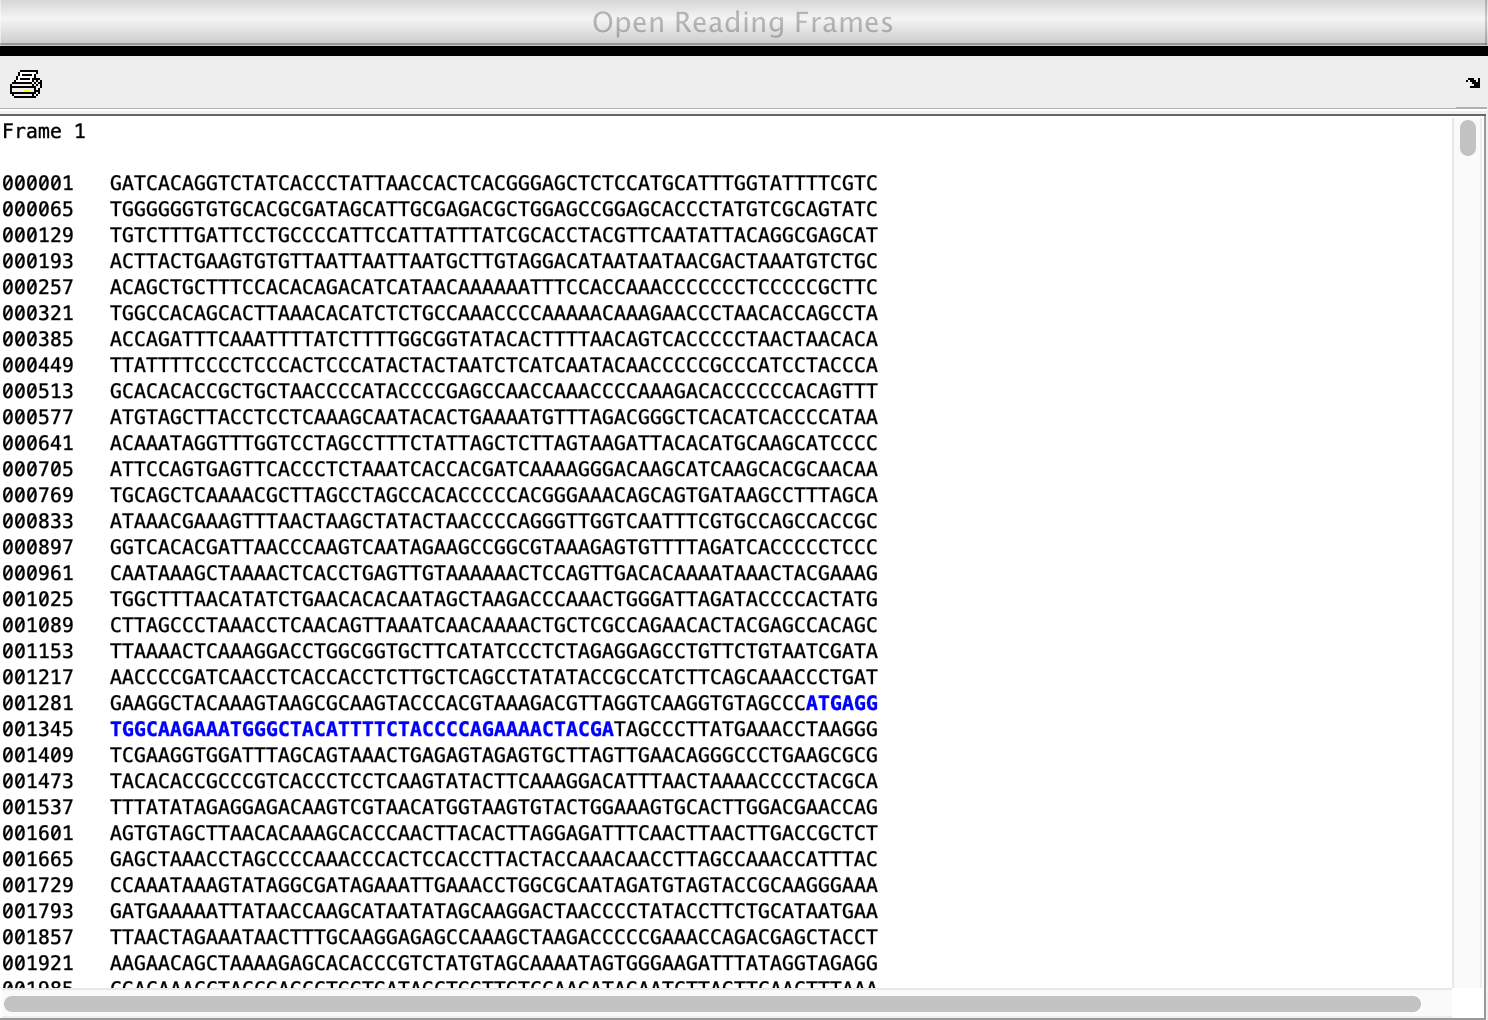

% Retrive ORFs from the data
structure = seqshoworfs(data);

structure

structure = 1×3 struct array with fields:
    Start
    Stop


**Codons:**

In the first place, the probability of non-stop codons is calculated. TAA, TAG and TGA are stop codons in the DNA. Moreover, using the **codoncount** function, it is possible to observe that the codons are not uniformly distributed since some codons appear more frequently than others.

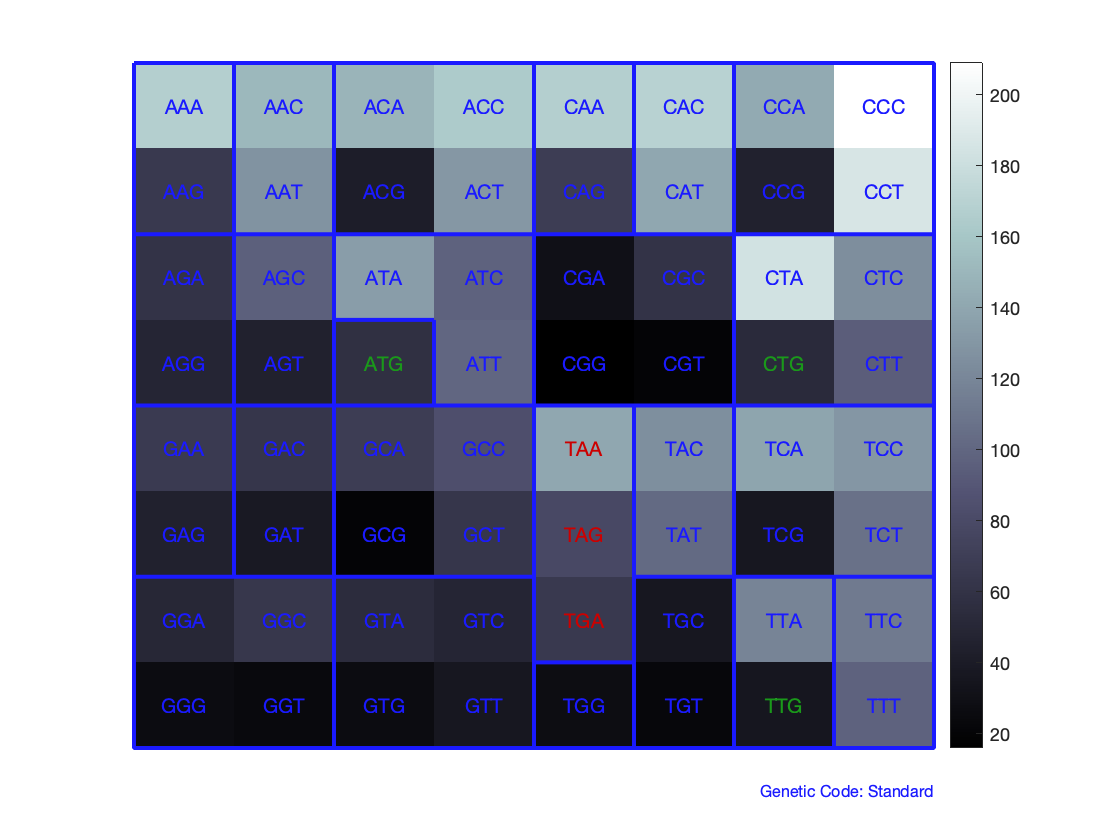

% Plot distribution of Codons
figure;
[codons, codonArray] = codoncount(data, 'figure', true);	

codons

codons = struct with fields:
    AAA: 168
    AAC: 151
    AAG: 66
    AAT: 128
    ACA: 149
    ACC: 164
    ACG: 42
    ACT: 131
    AGA: 61
    AGC: 96
    AGG: 49
    AGT: 45
    ATA: 135
    ATC: 98
    ATG: 58
    ATT: 100
    CAA: 168
    CAC: 170
    CAG: 69
    CAT: 141
    CCA: 142
    CCC: 209
    CCG: 45
    CCT: 187
    CGA: 31
    CGC: 61
    CGG: 16
    CGT: 20
    CTA: 184
    CTC: 125
    CTG: 53
    CTT: 95
    GAA: 67
    GAC: 63
    GAG: 45
    GAT: 38
    GCA: 69
    GCC: 84
    GCG: 20
    GCT: 63
    GGA: 50
    GGC: 64
    GGG: 27
    GGT: 25
    GTA: 55
    GTC: 49
    GTG: 27
    GTT: 37
    TAA: 141
    TAC: 126
    TAG: 79
    TAT: 102
    TCA: 139
    TCC: 130
    TCG: 37
    TCT: 107
    TGA: 66
    TGC: 37
    TGG: 28
    TGT: 23
    TTA: 119
    TTC: 113
    TTG: 36
    TTT: 98


Given that, the probability of non-stop codons is calculated as follows: 

*probability_stop = P(TAA) + P(TAG) + P(TGA)*

*probability_nonStop = 1 - probability_stop*

% Calculate total amount of codons
codonVector = reshape(codonArray, [1, 64]);
total_codons = 0;
for i = 1:length(codonVector)
    total_codons = total_codons + codonVector(i);
end 
total_codons

total_codons = 5521

% Probability of stop codons 
probability_stop = (codons.("TAA") + codons.("TAG") + codons.("TGA"))/total_codons

probability_stop = 0.0518

% Probability of non-stop codons 
probability_nonStop = 1 - probability_stop

probability_nonStop = 0.9482

Moreover, knowing the following inequality:


$${\left(\mathrm{probability}\_\mathrm{nonStop}\right)}^k <p$$


it possible to retrive the value of *k* for different probabilities *p. *Where *p* is the probability that a real gene is longer that would be expected by chance.

% Extract the value of k

% Calculate k with p = 90%
p1 = 0.90;
k1 = log((1 - p1))/log(probability_nonStop)

k1 = 43.2881

% Calculate k with p = 95.5%
p2 = 0.955;
k2 = log((1 - p2))/log(probability_nonStop)

k2 = 58.2998

Finally, the length of the ORFs is calculated and compared to the values of *k*. From this comparison we obtain the following information: 

- 21 ORFs contain real genes with probability 90%

- 13 ORFs contain real genes with probability 95.5%

From these results, we can conclude that different probabilities lead to different accuracies and numbers of ORFs with real genes. Moreover, with *p* equal to 95.5% the count is equal to the exact number of coding genes of the mitochondria of neanderthals: 13.

% Count ORF with length less than k 
count1 = 0;
count2 = 0;

for i = 1:3
    start_ORF = structure(i).Start;
    end_ORF = structure(i).Stop;

    for j = 1:length(end_ORF)
        length_ORF = ((end_ORF(j) - start_ORF(j))/3);

        % k with p = 90% is checked
        if length_ORF > k1
            count1 = count1 + 1;
            
            % k with p = 95.5% is checked
            if length_ORF > k2
                count2 = count2 + 1;
            end
        end  
    end
end

count1

count1 = 21

count2

count2 = 13

**2. Using what you have learnt above explore the neanderthal mitochondrial genome and find at least one *****interesting***** feature.**			

While Codons and ORFs are analysed in the previous section, there exists other features such as Bases, Density and Dimers to be examined in the neanderthal mitochondrial genome.

**Bases:**

% Retrieve bases and possible ambigous elements of the data
bases = basecount(data, 'Ambiguous', 'individual')

bases = struct with fields:
    A: 5107
    C: 5174
    G: 2180
    T: 4104
    R: 0
    Y: 0
    K: 0
    M: 0
    S: 0
    W: 0
    B: 0
    D: 0
    H: 0
    V: 0
    N: 0


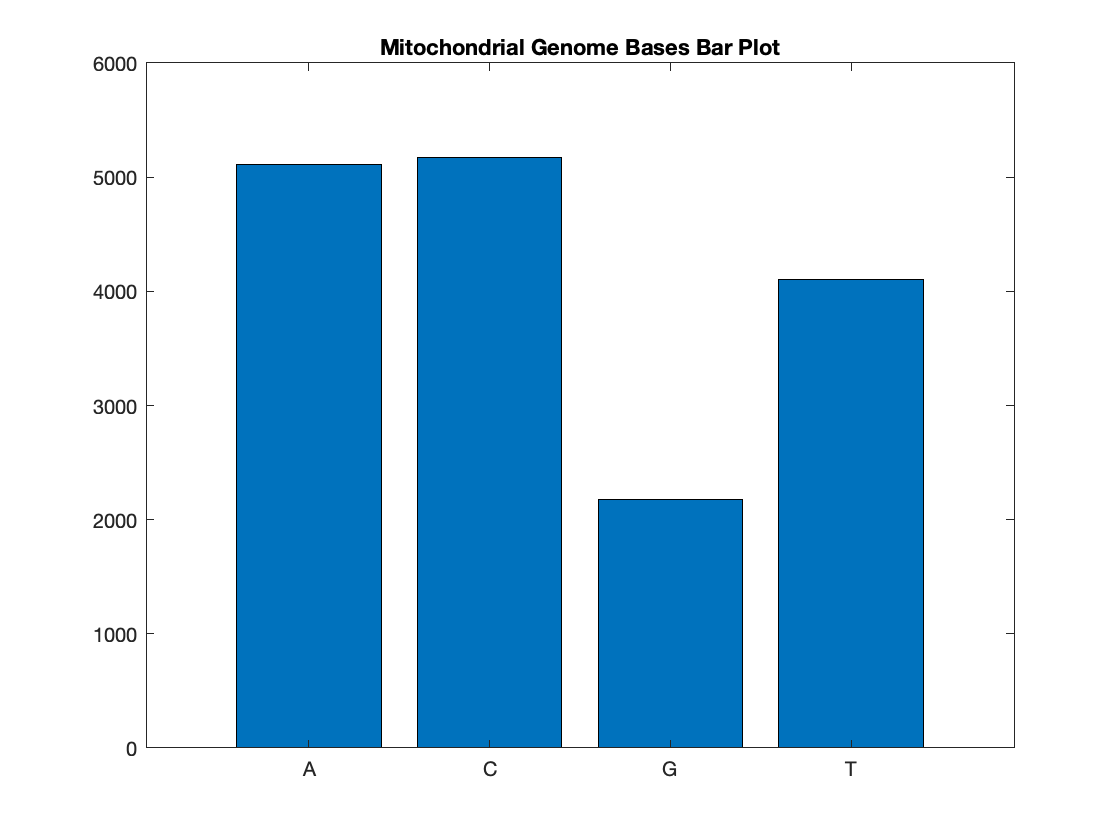

% Plot of the bases
figure;
X = categorical({'A','C','G','T'});
X = reordercats(X, {'A','C','G','T'});
bar(X, [bases.A, bases.C, bases.G, bases.T]);
title('Mitochondrial Genome Bases Bar Plot');

By analysing this plot, it is possible to conclude the following: 

- A (Adenine): 5107, C (Cytosine): 5174, G (Guanine): 2180, T (Thymine): 4104

- There is a significant lack of Guanine 

- No ambiguous bases are present in the genome

**Density: **			

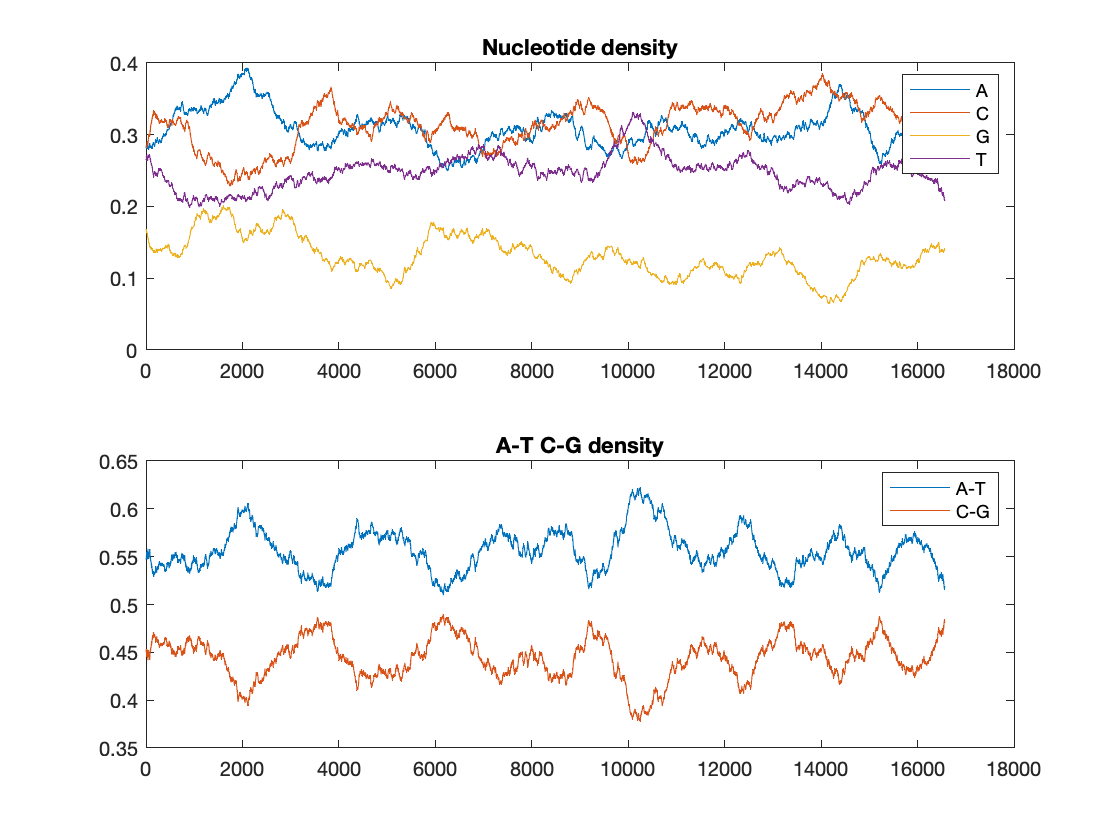

% Retrieve and analyse the density of the bases
figure;
density = ntdensity(data);

Next, the frequency of the bases is analysed. In these Density plots, there are no particular observations to be made other than the clear lack of Guanine, as also stated in the previous point. 

**Dimers: **

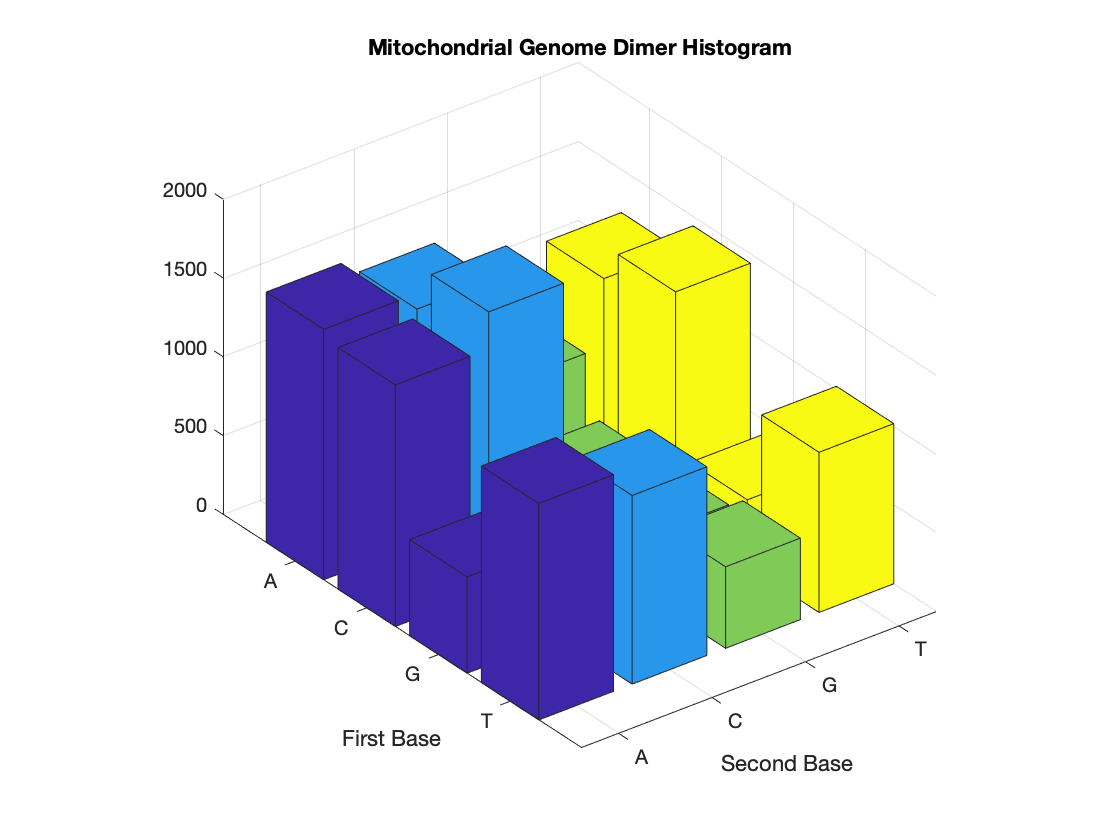

% Retrieve and analyse the Dimers
figure;
[dimers, percent] = dimercount(data, 'chart', 'bar');
title('Mitochondrial Genome Dimer Histogram');

dimers

dimers = struct with fields:
    AA: 1589
    AC: 1490
    AG: 799
    AT: 1229
    CA: 1533
    CC: 1769
    CG: 431
    CT: 1441
    GA: 611
    GC: 718
    GG: 432
    GT: 418
    TA: 1374
    TC: 1197
    TG: 517
    TT: 1016


Finally, the dimers of the genome are studied. From this analysis, it is again clear the lack of Guanine. Moreover, the frequency of the dimers is computed: 

% Display dimers frequency
figure;
dimers_frequency = array2table(percent);
dimers_frequency.Properties.RowNames = {'A','C','G','T'};
dimers_frequency.Properties.VariableNames = {'A','C','G','T'}

dimers_frequency = 4×4 table
            A           C           G           T    
         ________    ________    ________    ________

    A    0.095931    0.089954    0.048237    0.074197
    C     0.09255      0.1068     0.02602    0.086996
    G    0.036887    0.043347    0.026081    0.025235
    T    0.082951    0.072265    0.031212    0.061338


% Sum and display frequency of each base
figure;
frequency_sum = sum(percent);
dimers_frequencySum = array2table(frequency_sum);
dimers_frequencySum.Properties.VariableNames = {'A','C','G','T'};
dimers_frequencySum.Properties.RowNames = {'Total'}

dimers_frequencySum = 1×4 table
                A          C          G          T   
             _______    _______    _______    _______

    Total    0.30832    0.31236    0.13155    0.24777


From this table we can conclude that Cytosine has the highest frequency and it is the most frequent first base of the dimers. 